% read the bag
bag = ros2bagreader("soft_gripper_expts/expt_soft_gripper_expt1/")

bag =   ros2bagreader with properties:

           FilePath: '/home/barracuda/colcon_ws/src/ral_2026/scripts/lattice_characterization_scripts/soft_gripper_expts/expt_soft_gripper_expt1'
      AvailableBags: "expt_soft_gripper_expt1_0.db3"
          StartTime: 1.7853e+09
            EndTime: 1.7853e+09
    AvailableTopics: [7×3 table]
    AvailableFrames: {20×1 cell}
        MessageList: [31131×3 table]
        NumMessages: 31131


bag.AvailableTopics

ans = 7×3 table
                                                     NumMessages           MessageType                                                                                                                                                                                                                                                                                                                                                                                                                                                                      MessageDefinition                                                                                                                                                                                                                                                                                                                                                                                        

%read messages from /area_sensor/float_array
%/object_linear_encoder/float_array
start_time = bag.StartTime;
area_bag = select(bag,"Topic","/area_sensor/float_array");
area_msgs = readMessages(area_bag);

n = size(area_msgs,1);
timestamp = zeros(n,1,"double");
area_data = zeros(n,8,"double");

for i=1:n
    timestamp(i) = area_msgs{i}.data(1);
    current_area = area_msgs{i}.data(2:9);
    area_data(i,1:end) = current_area';
end

timestamp = timestamp - start_time;
for i = 1:n
    if timestamp(i)>0
        break
    end
    timestamp(i) = [];
    area_data(1,:) = [];
end

n = size(timestamp,1);

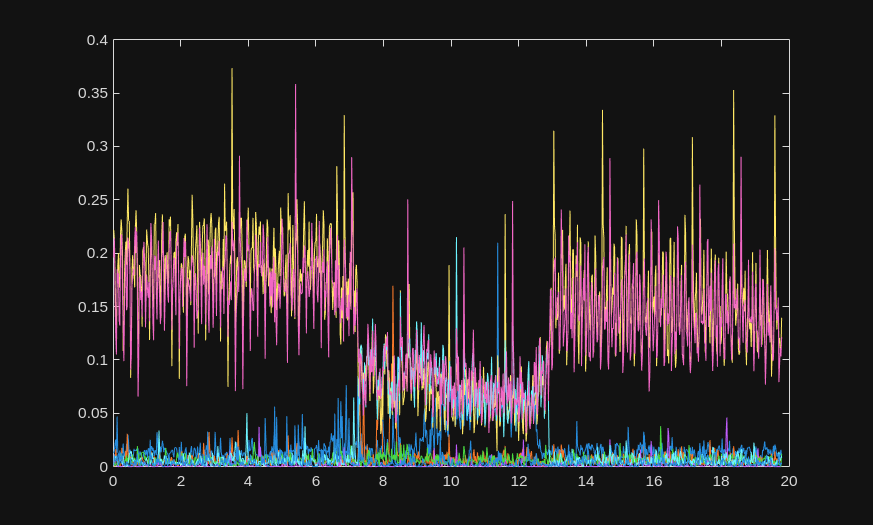

% plot unprocessed area
plot(timestamp,area_data(1:end,1));
hold on;
plot(timestamp,area_data(1:end,2));
plot(timestamp,area_data(1:end,3));
plot(timestamp,area_data(1:end,4));
plot(timestamp,area_data(1:end,5));
plot(timestamp,area_data(1:end,6));
plot(timestamp,area_data(1:end,7));
plot(timestamp,area_data(1:end,8));
hold off;

% now process

area_data(1:end,1) = (area_data(1:end,1) - min(area_data(1:end,1)))/(max(area_data(1:end,1)) - min(area_data(1:end,1)));
area_data(1:end,2) = (area_data(1:end,2) - min(area_data(1:end,2)))/(max(area_data(1:end,2)) - min(area_data(1:end,2)));
area_data(1:end,3) = (area_data(1:end,3) - min(area_data(1:end,3)))/(max(area_data(1:end,3)) - min(area_data(1:end,3)));
area_data(1:end,4) = (area_data(1:end,4) - min(area_data(1:end,4)))/(max(area_data(1:end,4)) - min(area_data(1:end,4)));
area_data(1:end,5) = (area_data(1:end,5) - min(area_data(1:end,5)))/(max(area_data(1:end,5)) - min(area_data(1:end,5)));
area_data(1:end,6) = (area_data(1:end,6) - min(area_data(1:end,6)))/(max(area_data(1:end,6)) - min(area_data(1:end,6)));
area_data(1:end,7) = (area_data(1:end,7) - min(area_data(1:end,7)))/(max(area_data(1:end,7)) - min(area_data(1:end,7)));
area_data(1:end,8) = (area_data(1:end,8) - min(area_data(1:end,8)))/(max(area_data(1:end,8)) - min(area_data(1:end,8)));

area_data = lowpass(area_data,0.5);

area_data(:,3) = 0.8-area_data(:,3);
area_data(:,7) = 0.8-area_data(:,7);

area_data(:,1) = area_data(:,1) - min(area_data(:,1));
area_data(:,1) = area_data(:,2) - min(area_data(:,2));
area_data(:,1) = area_data(:,3) - min(area_data(:,3));
area_data(:,1) = area_data(:,4) - min(area_data(:,4));
area_data(:,1) = area_data(:,5) - min(area_data(:,5));
area_data(:,1) = area_data(:,6) - min(area_data(:,6));
area_data(:,1) = area_data(:,7) - min(area_data(:,7));
area_data(:,1) = area_data(:,8) - min(area_data(:,8));

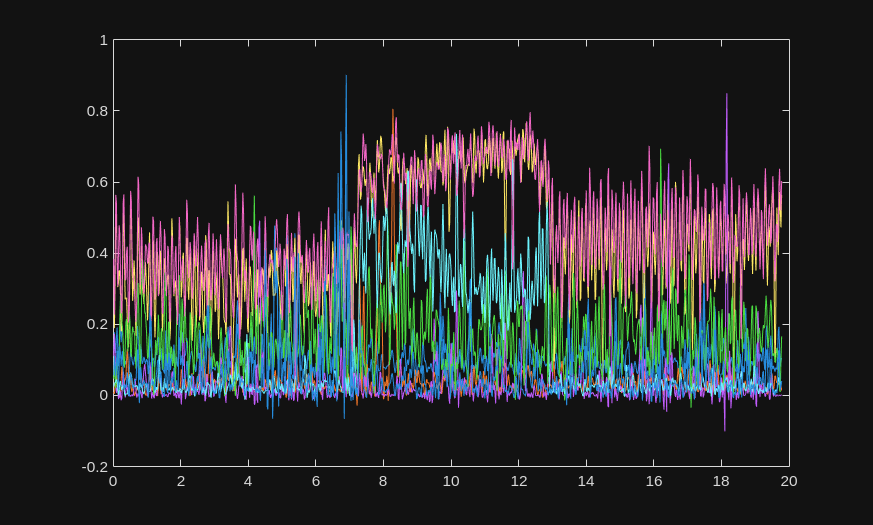


plot(timestamp,area_data(1:end,1));
hold on;
plot(timestamp,area_data(1:end,2));
plot(timestamp,area_data(1:end,3));
plot(timestamp,area_data(1:end,4));
plot(timestamp,area_data(1:end,5));
plot(timestamp,area_data(1:end,6));
plot(timestamp,area_data(1:end,7));
plot(timestamp,area_data(1:end,8));
hold off;

% that was area, now get the delta_x from voltage
linear_encoder_bag = select(bag,"Topic","/object_linear_encoder/float_array");
linear_encoder_msgs = readMessages(linear_encoder_bag);

le_n = size(linear_encoder_msgs,1);
le_unsynced = zeros(le_n,1,"double");
le_timestamp = zeros(le_n,1,"double");
for i=1:le_n
    le_timestamp(i) = linear_encoder_msgs{i}.data(1);
    le_unsynced(i) = linear_encoder_msgs{i}.data(2);
end
%
le_timestamp = le_timestamp - start_time;
for i = 1:le_n
    if le_timestamp(i) > 0
        break
    end
    le_timestamp(i) = [];
    le_unsynced(i) = [];
end

le_unsynced(1:3) = [];
le_timestamp(1:3) = [];

le = le_unsynced;
% the required data is in le
x = m*le + c;

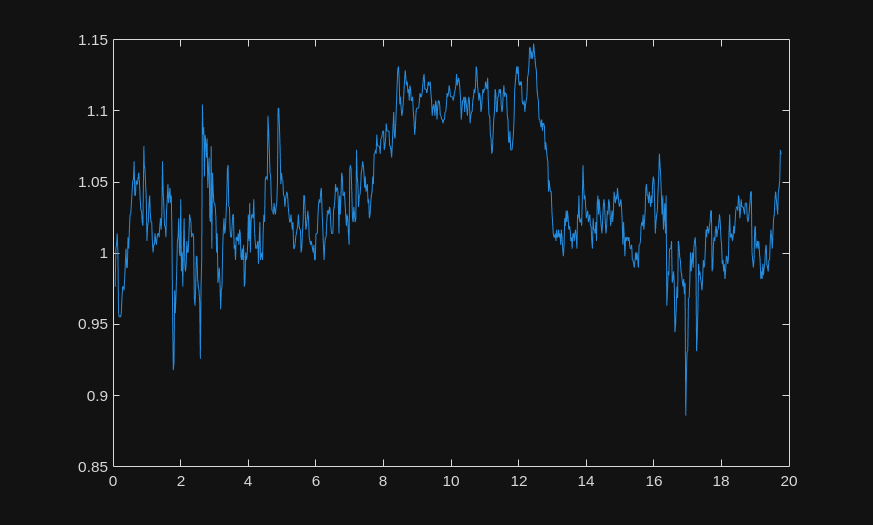

plot(le_timestamp,x);

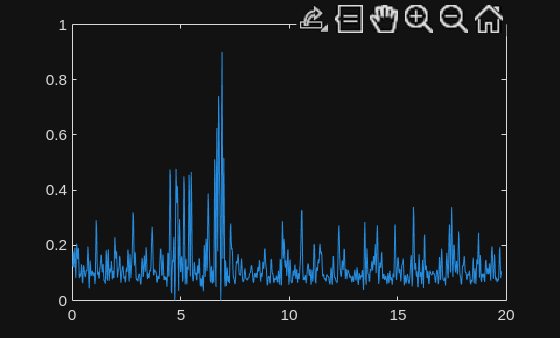

% between time stamps 8 to 15 calculate the pfd


% the object image
% lattice characterization
% gripper images
% handover video
plot(timestamp,area_data(:,1));